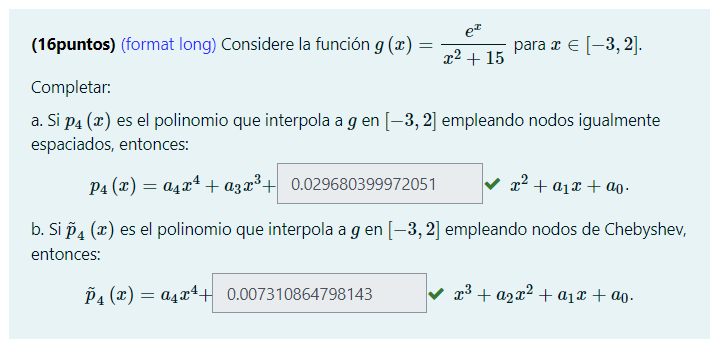

syms x
f = exp(x)/(x^2 + 15)

$$f = \frac{{\mathrm{e}}^{x}}{x^{2}+15}$$

f = matlabFunction(f,'Vars',{x});
a=-3; b=2;
n = 4 %Grado del polinomio

n = 4

xe = linspace(a,b,n+1)  % Nodos equidistanciados

xe =    -3.0000   -1.7500   -0.5000    0.7500    2.0000


ye = f(xe)

ye =     0.0021    0.0096    0.0398    0.1360    0.3889


[Cn, D] = newpoly (xe, ye) 

Cn =     0.0008    0.0073    0.0297    0.0662    0.0663


D =     0.0021         0         0         0         0
    0.0096    0.0060         0         0         0
    0.0398    0.0241    0.0072         0         0
    0.1360    0.0770    0.0212    0.0037         0
    0.3889    0.2023    0.0501    0.0077    0.0008


xp = a:n+1:b    

xp =     -3     2


[C, X, Y] = cheby (f, n, a, b)

C =     0.1136    0.1705    0.0777    0.0223    0.0039


X =     1.8776    0.9695   -0.5000   -1.9695   -2.8776


Y =     0.3529    0.1654    0.0398    0.0074    0.0024


[Cn, D] = newpoly (X, Y) 

Cn =     0.0008    0.0073    0.0296    0.0660    0.0662


D =     0.3529         0         0         0         0
    0.1654    0.2065         0         0         0
    0.0398    0.0855    0.0509         0         0
    0.0074    0.0220    0.0216    0.0076         0
    0.0024    0.0055    0.0070    0.0038    0.0008


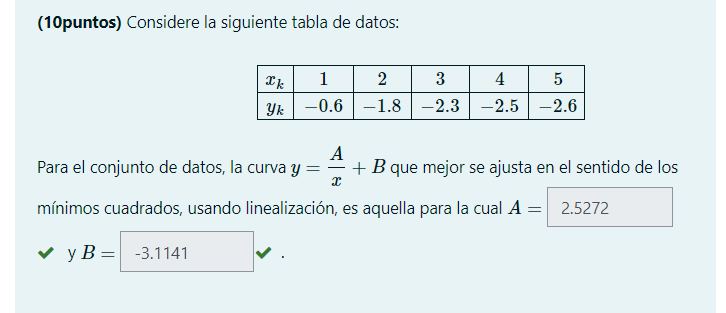

format short
X = [1 2 3 4 5]

X =      1     2     3     4     5


Y = [-0.6 -1.8 -2.3 -2.5 -2.6]

Y =    -0.6000   -1.8000   -2.3000   -2.5000   -2.6000



XT = (1./X)

XT =     1.0000    0.5000    0.3333    0.2500    0.2000



[A, B] = lsline (XT,Y)

A = 2.5272

B = -3.1141

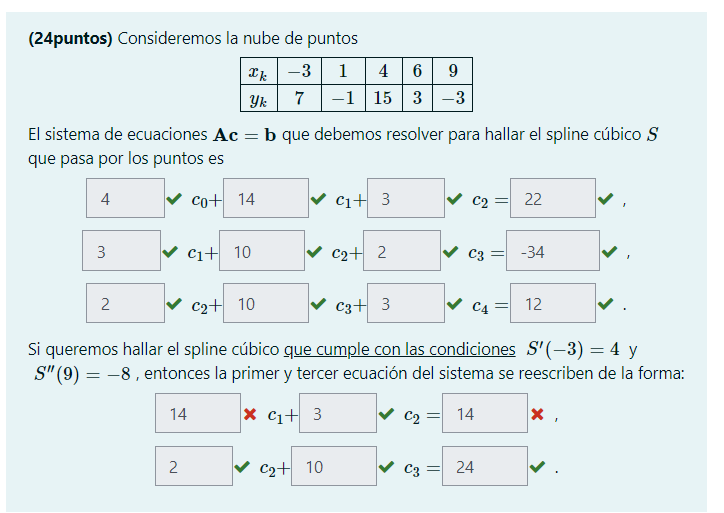

X = [-3 1 4 6 9]

X =     -3     1     4     6     9


Y = [7 -1 15 3 -3]

Y =      7    -1    15     3    -3



[Ac_base, B] = sistemabase(X,Y)

$$Ac\_base = \left(\begin{array}{c} 4\,c_{0}+14\,c_{1}+3\,c_{2}\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+10\,c_{3}+3\,c_{4} \end{array}\right)$$

B =     22
   -34
    12


% SISTEMA SUJETO
dsx0=4; dsxn=1;
[Ac_sujeto, B] = sistemasujeto(X,Y,dsx0,dsxn)

$$Ac\_sujeto = \left(\begin{array}{c} 12\,c_{1}+3\,c_{2}-9\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+\frac{17\,c_{3}}{2}-\frac{9}{2} \end{array}\right)$$

B =     22
   -34
    12


% SISTEMA CURVATURA
ddsx0=1; ddsxn=-8;
[Ac_curvatura, B] = sistemacurvatura(X,Y,ddsx0,ddsxn)

$$Ac\_curvatura = \left(\begin{array}{c} 14\,c_{1}+3\,c_{2}+2\\ 3\,c_{1}+10\,c_{2}+2\,c_{3}\\ 2\,c_{2}+10\,c_{3}-12 \end{array}\right)$$

B =     22
   -34
    12
